#     1. Transfer Learning

## Overview of Pretrained Convolutional Neural Networks

Load AlexNet into a network variable in MATLAB

[net, classes] = imagePretrainedNetwork("alexnet")    % Error? Then, install 'Deep Learning Toolbox Model for AlexNet Network' in Add-Ons Explorer

net =   dlnetwork - 속성 있음:

         Layers: [24×1 nnet.cnn.layer.Layer]
    Connections: [23×2 table]
     Learnables: [16×3 table]
          State: [0×3 table]
     InputNames: {'data'}
    OutputNames: {'prob'}
    Initialized: 1

  요약 보기(summary 참조).


classes = 1000×1 string 배열
    "tench"
    "goldfish"
    "great white shark"
    "tiger shark"
    "hammerhead"
    "electric ray"
    "stingray"
    "cock"
    "hen"
    "ostrich"
    "brambling"
    "goldfinch"
    "house finch"
    "junco"
    "indigo bunting"
    "robin"
    "bulbul"
    "jay"
    "magpie"
    "chickadee"
    "water ouzel"
    "kite"
    "bald eagle"
    "vulture"
    "great grey owl"
    "European fire salamander"
    "common newt"
    "eft"
    "spotted salamander"
    "axolotl"


Peek into AlexNet

% View the layers of AlexNet and save the layers to a variable
layers = net.Layers

layers =   다음 계층을 포함한 24×1 Layer 배열:

     1   'data'    영상 입력               227×227×3 영상 (정규화: 'zerocenter')
     2   'conv1'   2차원 컨벌루션          96개 11×11×3 컨벌루션(스트라이드: [4  4], 채우기: [0  0  0  0])
     3   'relu1'   ReLU                  ReLU
     4   'norm1'   교차 채널 정규화         교차 채널 정규화 (요소당 채널 5개)
     5   'pool1'   2차원 최댓값 풀링        3×3 최댓값 풀링 (스트라이드: [2  2], 채우기: [0  0  0  0])
     6   'conv2'   2차원 그룹화된 컨벌루션   2 groups of 128 5×5×48 컨벌루션(스트라이드: [1  1], 채우기: [2  2  2  2])
     7   'relu2'   ReLU                  ReLU
     8   'norm2'   교차 채널 정규화         교차 채널 정규화 (요소당 채널 5개)
     9   'pool2'   2차원 최댓값 풀링        3×3 최댓값 풀링 (스트라이드: [2  2], 채우기: [0  0  0  0])
    10   'conv3'   2차원 컨벌루션          384개 3×3×256 컨벌루션(스트라이드: [1  1], 채우기: [1  1  1  1])
    11   'relu3'   ReLU                  ReLU
    12   'conv4'   2차원 그룹화된 컨벌루션   2 groups of 192 3×3×192 컨벌루션(스트라이드: [1  1], 채우기: [1  1  1  1])
    13   'relu4'


% Save the first and last layers of AlexNet
layers_input = layers(1)

layers_input =   ImageInputLayer - 속성 있음:

                      Name: 'data'
                 InputSize: [227 227 3]
        SplitComplexInputs: 0

   하이퍼파라미터
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [227×227×3 single]


layers_output = layers(end)

layers_output =   SoftmaxLayer - 속성 있음:

    Name: 'prob'


## Preprocessing an Image

Import an image and resize it to be compatible with AlexNet

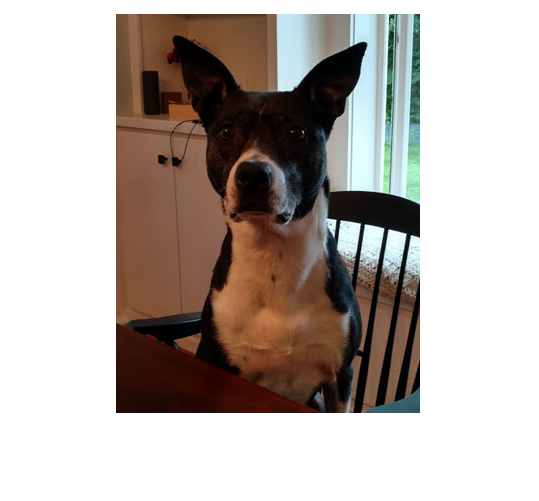

% Display an image
image_original = imread("harper.jpg");
imshow(image_original)


% View the input size of AlexNet
layers_input.InputSize

ans =    227   227     3



% Resize the image so that it can be applied to AlexNet
image_resized = imresize(image_original, [227, 227])

image_resized = 227×227×3 uint8 배열
image_resized(:,:,1) =

   110   110   112   114   116   116   114   118   129   148   151   150   146   147   148   139   133   121   108   115   124   127   126   124   121   121   120   119   117   115   112   111   110   108   108   108   111   109   107   104   102    98    91    89    86    84    82    78    73    73    72    71    70    68    69    72    76    79    79    77    75    76    76    78    78    78    76    77    80    82    83    81    80    80    81    81    81    80    80    80    81    81    82    81    81    81    81    81    81    80    79    80    81    81    82    81    80    81    81    81    82    79    78    79    79    80    80    80    80    79    79    86   118   132   130   129   128   127   126   119   163   199   200   198   196   196   196   195   195   194   194   190   190   192   191   192   191   185   181   180   178   174   167   163   161   156   153   152   151   150   148   144   140   138   135   131   13

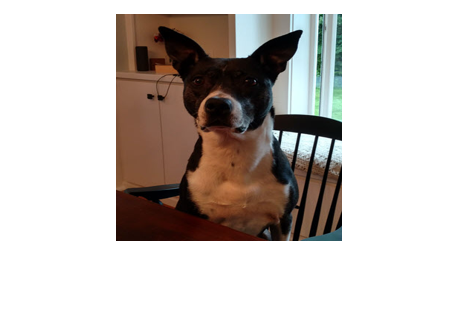

imshow(image_resized)


% Classify the image and see its score
im = single(image_resized)

im = 227×227×3 single 배열
im(:,:,1) =

   110   110   112   114   116   116   114   118   129   148   151   150   146   147   148   139   133   121   108   115   124   127   126   124   121   121   120   119   117   115   112   111   110   108   108   108   111   109   107   104   102    98    91    89    86    84    82    78    73    73    72    71    70    68    69    72    76    79    79    77    75    76    76    78    78    78    76    77    80    82    83    81    80    80    81    81    81    80    80    80    81    81    82    81    81    81    81    81    81    80    79    80    81    81    82    81    80    81    81    81    82    79    78    79    79    80    80    80    80    79    79    86   118   132   130   129   128   127   126   119   163   199   200   198   196   196   196   195   195   194   194   190   190   192   191   192   191   185   181   180   178   174   167   163   161   156   153   152   151   150   148   144   140   138   135   131   131   132   134   137  

scores = minibatchpredict(net, im)

scores = 1×1000 single 행 벡터
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


[testPred, score] = scores2label(scores, classes)

testPred = categorical
     Boston bull 


score = single
0.6152

## Image Datastore

When you import large data, you don't have to save them as variables because it costs too much time and memory. 

Instead, you can read image files by creating a datastore, which references a data source such as a folder of image files. When you create a datastore, basic information such as the file name and formats is stored.

% Create an image datastore referring to 'Lucy'
imageDS = imageDatastore("/Users/eukkcha/Desktop/Sejong/AI/petImages/Lucy",...
    "IncludeSubfolders",true,"LabelSource","foldernames")

imageDS =   ImageDatastore - 속성 있음:

                       Files: {
                              '/Users/eukkcha/Desktop/Sejong/AI/petImages/Lucy/Lucy103.jpg';
                              '/Users/eukkcha/Desktop/Sejong/AI/petImages/Lucy/Lucy104.jpg';
                              '/Users/eukkcha/Desktop/Sejong/AI/petImages/Lucy/Lucy105.jpg'
                               ... and 29 more
                              }
                     Folders: {
                              '/Users/eukkcha/Desktop/Sejong/AI/petImages/Lucy'
                              }
                      Labels: [Lucy; Lucy; Lucy ... and 29 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


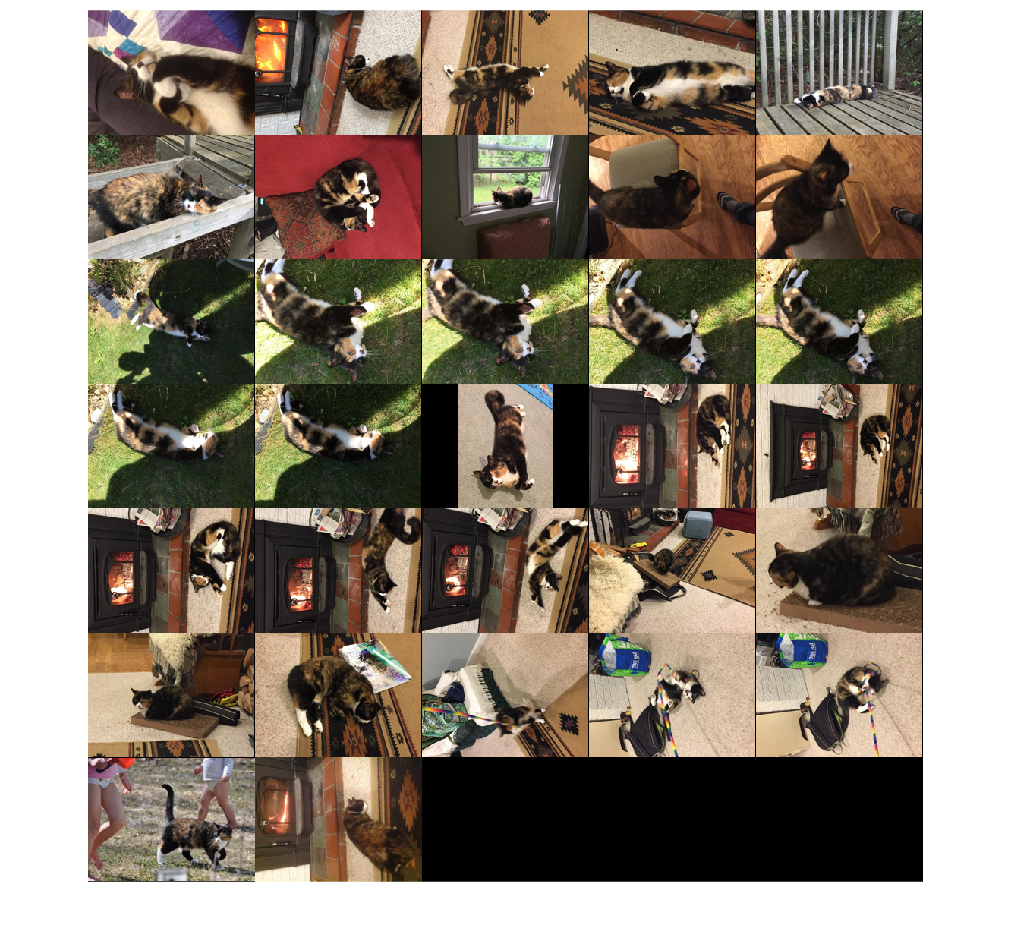

% Read and display 'Lucy' images
montage(imageDS)

For the images in an image datastore, basic preprocessing can be done by `augmentedImageDatastore` function

augImageDS = augmentedImageDatastore([227, 227],imageDS)

augImageDS =   augmentedImageDatastore - 속성 있음:

             NumObservations: 32
                       Files: {32×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'none'
                  OutputSize: [227 227]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


## Modifying a Pretrained Network

An existing pretrained network does not ouput the classes you want. When performing transfer learning, you will typically change the fully connected layer and the classification layer to suit your specific application. 

clear    % clear
% Load AlexNet and view the layers
net = imagePretrainedNetwork("alexnet")

net =   dlnetwork - 속성 있음:

         Layers: [24×1 nnet.cnn.layer.Layer]
    Connections: [23×2 table]
     Learnables: [16×3 table]
          State: [0×3 table]
     InputNames: {'data'}
    OutputNames: {'prob'}
    Initialized: 1

  요약 보기(summary 참조).


layers = net.Layers

layers =   다음 계층을 포함한 24×1 Layer 배열:

     1   'data'    영상 입력               227×227×3 영상 (정규화: 'zerocenter')
     2   'conv1'   2차원 컨벌루션          96개 11×11×3 컨벌루션(스트라이드: [4  4], 채우기: [0  0  0  0])
     3   'relu1'   ReLU                  ReLU
     4   'norm1'   교차 채널 정규화         교차 채널 정규화 (요소당 채널 5개)
     5   'pool1'   2차원 최댓값 풀링        3×3 최댓값 풀링 (스트라이드: [2  2], 채우기: [0  0  0  0])
     6   'conv2'   2차원 그룹화된 컨벌루션   2 groups of 128 5×5×48 컨벌루션(스트라이드: [1  1], 채우기: [2  2  2  2])
     7   'relu2'   ReLU                  ReLU
     8   'norm2'   교차 채널 정규화         교차 채널 정규화 (요소당 채널 5개)
     9   'pool2'   2차원 최댓값 풀링        3×3 최댓값 풀링 (스트라이드: [2  2], 채우기: [0  0  0  0])
    10   'conv3'   2차원 컨벌루션          384개 3×3×256 컨벌루션(스트라이드: [1  1], 채우기: [1  1  1  1])
    11   'relu3'   ReLU                  ReLU
    12   'conv4'   2차원 그룹화된 컨벌루션   2 groups of 192 3×3×192 컨벌루션(스트라이드: [1  1], 채우기: [1  1  1  1])
    13   'relu4'

Change the number of output classes by modifying the fully conneceted layer(23).

layers(23) = fullyConnectedLayer(14);

## Preparing Training Data

% Create an image datastore with the images labeled by their folder name
imageDS = imageDatastore("/Users/eukkcha/Desktop/Sejong/AI/petImages",...
    "IncludeSubfolders",true,"LabelSource","foldernames") % IncludeSubfolders=true,LabelSource="foldernames")

imageDS =   ImageDatastore - 속성 있음:

                       Files: {
                              '/Users/eukkcha/Desktop/Sejong/AI/petImages/Casey/1.jpg';
                              '/Users/eukkcha/Desktop/Sejong/AI/petImages/Casey/10.jpg';
                              '/Users/eukkcha/Desktop/Sejong/AI/petImages/Casey/100.png'
                               ... and 1353 more
                              }
                     Folders: {
                              '/Users/eukkcha/Desktop/Sejong/AI/petImages'
                              }
                      Labels: [Casey; Casey; Casey ... and 1353 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


classNames = categories(imageDS.Labels)

classNames = 14×1 cell 배열
    {'Casey'   }
    {'Dalek'   }
    {'Dylan'   }
    {'Ginny'   }
    {'Hamish'  }
    {'Harper'  }
    {'Kima'    }
    {'Legion'  }
    {'Leo'     }
    {'Lucy'    }
    {'Madeline'}
    {'Scottie' }
    {'Sherlock'}
    {'Susan'   }



% Split the data into training and test data sets
[trainImages, testImages] = splitEachLabel(imageDS, 0.8)

trainImages =   ImageDatastore - 속성 있음:

                       Files: {
                              '/Users/eukkcha/Desktop/Sejong/AI/petImages/Casey/1.jpg';
                              '/Users/eukkcha/Desktop/Sejong/AI/petImages/Casey/10.jpg';
                              '/Users/eukkcha/Desktop/Sejong/AI/petImages/Casey/100.png'
                               ... and 1083 more
                              }
                     Folders: {
                              '/Users/eukkcha/Desktop/Sejong/AI/petImages'
                              }
                      Labels: [Casey; Casey; Casey ... and 1083 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


testImages =   ImageDatastore - 속성 있음:

                       Files: {
                              '/Users/eukkcha/Desktop/Sejong/AI/petImages/Casey/75.jpg';
                              '/Users/eukkcha/Desktop/Sejong/AI/petImages/Casey/76.jpg';
                              '/Users/eukkcha/Desktop/Sejong/AI/petImages/Casey/77.jpg'
                               ... and 267 more
                              }
                     Folders: {
                              '/Users/eukkcha/Desktop/Sejong/AI/petImages'
                              }
                      Labels: [Casey; Casey; Casey ... and 267 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage



% Create augmented datastores to resize the images so that they can be applied to AlexNet
trainData = augmentedImageDatastore([227, 227], trainImages)

trainData =   augmentedImageDatastore - 속성 있음:

             NumObservations: 1086
                       Files: {1086×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'none'
                  OutputSize: [227 227]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


testData = augmentedImageDatastore([227, 227], testImages)

testData =   augmentedImageDatastore - 속성 있음:

             NumObservations: 270
                       Files: {270×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'none'
                  OutputSize: [227 227]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


## Training Options

Use Stochastic Gradient Descent with Momentum (SGDM) and decrease the initial learning rate to 0.0001.

The default initial learning rate is 0.01 but generally it should be decreased for better performances in a transfer learning.

opts = trainingOptions("sgdm","InitialLearnRate",0.0001,...
    "Plots","training-progress","Metrics","accuracy")

opts =   TrainingOptionsSGDM - 속성 있음:

                        Momentum: 0.9000
                InitialLearnRate: 1.0000e-04
                       MaxEpochs: 30
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                   MiniBatchSize: 128
                         Shuffle: 'once'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: []
             ValidationFrequency: 50
              ValidationPatience: Inf
             ObjectiveMetricName: 'loss'
                  CheckpointPath: '

## Training and Evaluating the Network

Train a new network. In order to use a GPU instead of a CPU, install 'Parallel Computing Toolbox' in Add-Ons explorer. A GPU is much faster than a CPU in training a neural network.

    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    TrainingAccuracy
    _________    _____    ___________    _________    ____________    ________________
            1        1       00:00:06       0.0001          5.4904              7.0312
           50        7       00:02:43       0.0001          1.5374              53.125
          100       13       00:05:10       0.0001         0.81059              72.656
          150       19       00:07:31       0.0001         0.46661              83.594
          200       25       00:09:51       0.0001         0.39244              89.062
          240       30       00:11:47       0.0001         0.26714              90.625
훈련이 중지됨: 최대 Epoch 완료됨


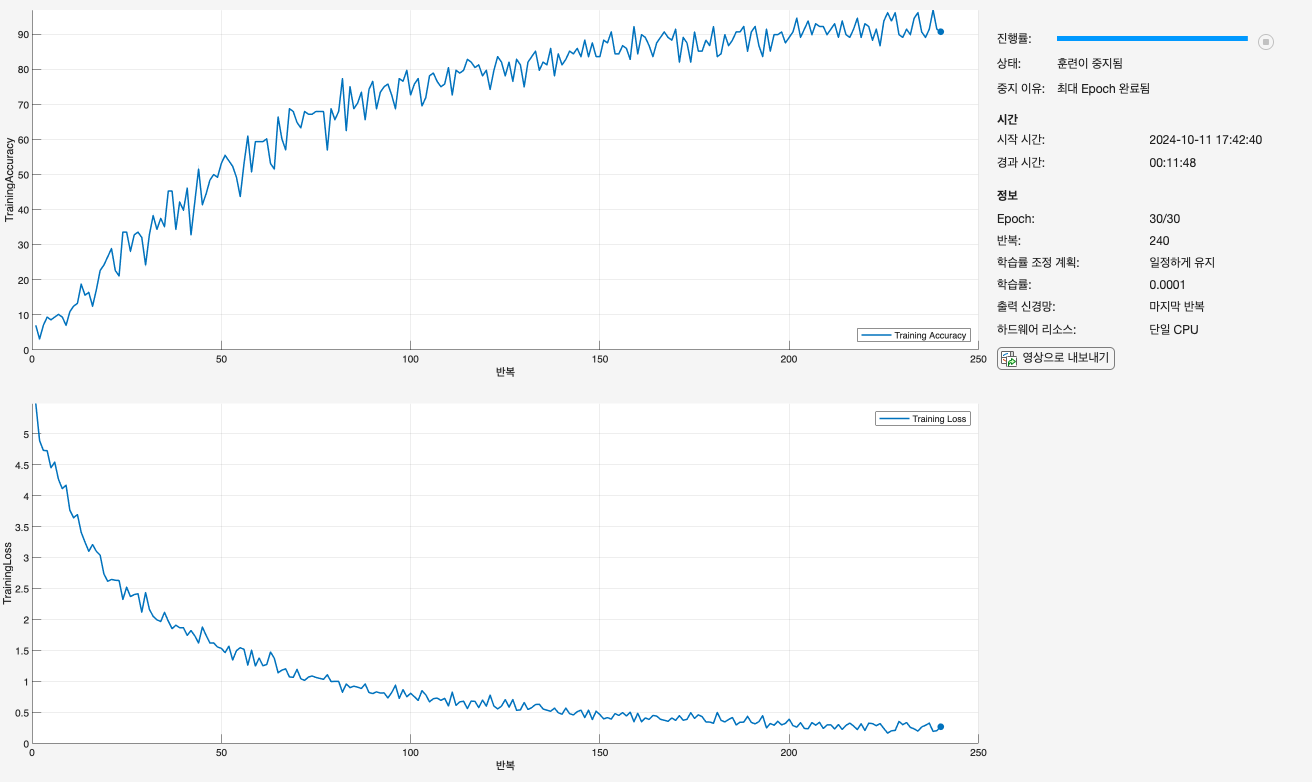

newnet =   dlnetwork - 속성 있음:

         Layers: [24×1 nnet.cnn.layer.Layer]
    Connections: [23×2 table]
     Learnables: [16×3 table]
          State: [0×3 table]
     InputNames: {'data'}
    OutputNames: {'prob'}
    Initialized: 1

  요약 보기(summary 참조).


newnet = trainnet(trainData,layers,"crossentropy",opts)

Evaluate the network by classifying the test data

scores = minibatchpredict(newnet,testData)    % Prediction by the new network

scores = 270×14 single 행렬
    0.8153    0.0008    0.0009    0.0009    0.0020    0.0038    0.0022    0.0025    0.0809    0.0047    0.0007    0.0283    0.0559    0.0012
    0.2712    0.0004    0.0003    0.0096    0.0028    0.0022    0.0011    0.0019    0.0076    0.0023    0.0128    0.6794    0.0033    0.0051
    0.0594    0.0007    0.0003    0.0114    0.0014    0.0017    0.0022    0.0043    0.0070    0.0031    0.0135    0.8878    0.0016    0.0056
    0.4794    0.0009    0.0006    0.0074    0.0066    0.0029    0.0003    0.0035    0.0544    0.0015    0.0054    0.4287    0.0035    0.0048
    0.1635    0.0009    0.0001    0.0052    0.0009    0.0049    0.0013    0.0009    0.0070    0.0097    0.0106    0.7658    0.0121    0.0171
    0.9996    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0000    0.0000    0.0000    0.0001    0.0000
    0.8721    0.0497    0.0005    0.0176    0.0008    0.0082    0.0041    0.0057    0.0012    0.0053    0.0062    0.0104    0.00

[testPred,score] = scores2label(scores,classNames)

testPred = 270×1 categorical 배열
     Casey 
     Scottie 
     Scottie 
     Casey 
     Scottie 
     Casey 
     Casey 
     Casey 
     Casey 
     Casey 
     Casey 
     Casey 
     Casey 
     Casey 
     Casey 
     Casey 
     Casey 
     Casey 
     Casey 
     Casey 
     Casey 
     Casey 
     Casey 
     Casey 
     Casey 
     Casey 
     Casey 
     Dalek 
     Casey 
     Dalek 


score = 270×1 single 열 벡터
    0.8153
    0.6794
    0.8878
    0.4794
    0.7658
    0.9996
    0.8721
    1.0000
    0.9999
    1.0000



testGT = testImages.Labels    % Ground truth of the test data

testGT = 270×1 categorical 배열
     Casey 
     Casey 
     Casey 
     Casey 
     Casey 
     Casey 
     Casey 
     Casey 
     Casey 
     Casey 
     Casey 
     Casey 
     Casey 
     Casey 
     Casey 
     Casey 
     Casey 
     Casey 
     Casey 
     Casey 
     Casey 
     Casey 
     Casey 
     Casey 
     Casey 
     Casey 
     Casey 
     Dalek 
     Dalek 
     Dalek 


testAcc = sum(testGT == testPred) / numel(testGT)    % Prediction Accuracy 

testAcc = 0.7074

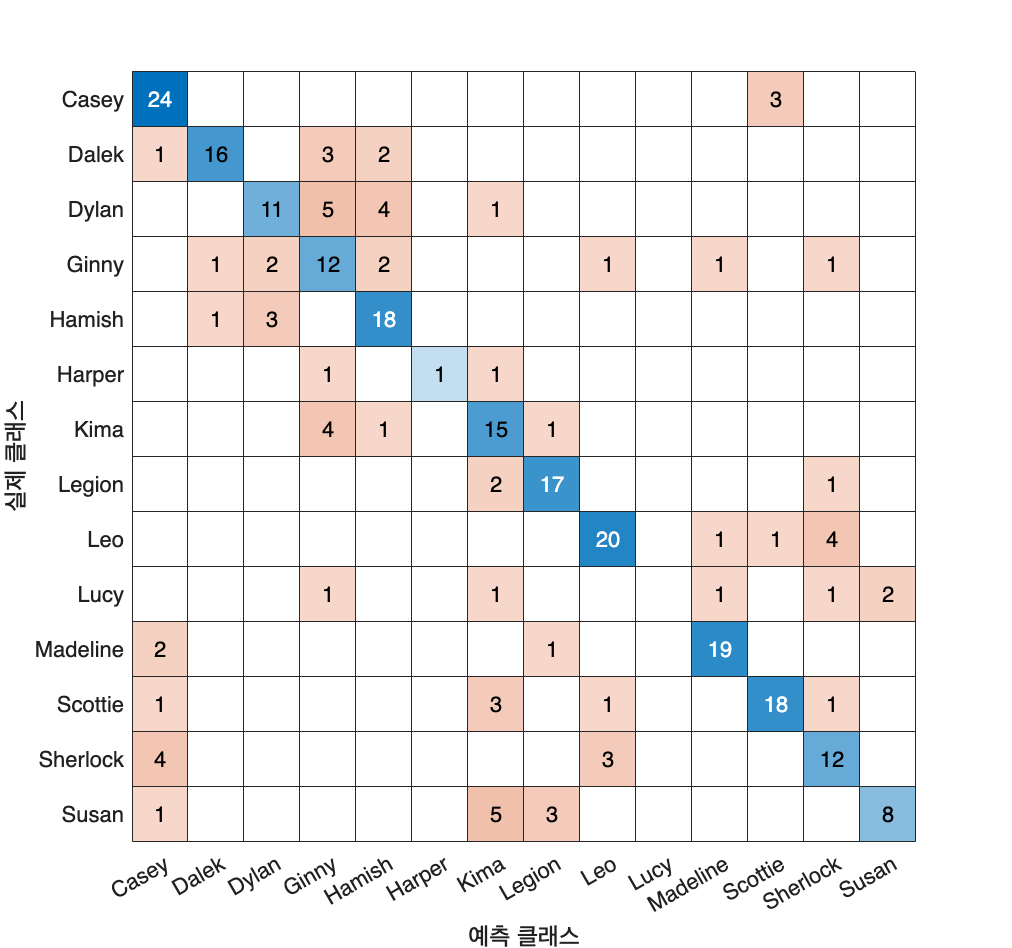

% 또는 nnz(testGT == testPred) / numel(testGT)
confusionchart(testGT,testPred)    % Visualization in a confusion matrix     